% Define the state-space matrices
A = [0, 1; -3, -4];
B = [1; 1];
C = [1, 2];
D = 0;

% Create the state-space system
sys = ss(A, B, C, D);
m_p = idpoly(sys)

m_p =
Continuous-time OE model: y(t) = [B(s)/F(s)]u(t) + e(t)
  B(s) = 3 s - 1                                       
                                                       
  F(s) = s^2 + 4 s + 3                                 
                                                       
Parameterization:
   Polynomial orders:
   nb=2   nf=2
   nk=0
   Number of free coefficients: 4
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                         
Created by direct construction or transformation. Not estimated.


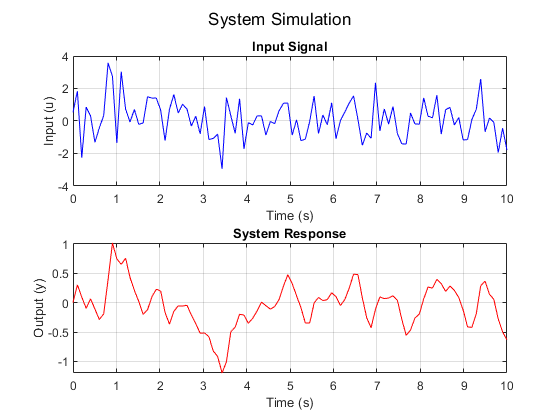

% Define the number of points
num_points = 100;  % Set your desired number of points

% Define simulation parameters
T = 10;  % Total simulation time in seconds
t = linspace(0, T, num_points);  % Time vector with specified number of points

% Generate random input data
rng(0);  % Set random seed for reproducibility
u = randn(length(t), 1);  % Random input signal

% Simulate the system response to the random input
[y, t_out, x] = lsim(sys, u, t);

% Create subplots
figure;

% Plot the input signal
subplot(2, 1, 1);
plot(t, u, 'b-');
title('Input Signal');
xlabel('Time (s)');
ylabel('Input (u)');
grid on;

% Plot the system response
subplot(2, 1, 2);
plot(t_out, y, 'r-');
title('System Response');
xlabel('Time (s)');
ylabel('Output (y)');
grid on;

% Adjust layout
sgtitle('System Simulation');

system identification using sps

% arx model
% A = [1, a_1, a_2] % A = [1, -4, -3]
% B = [0, b2]
% C = [1, c], take c= 0
% D = 0 

% Define confidence probability and number of random signs
% Define SPS parameters
m = 100;   % Integer m
q = 5;    % Integer q 
p = 1-q/m %Confidence probability p = 1 − q/m

p = 0.9500

T = 1;
% Create an instance of SPS
sps = SPS(p, m, q, n, T);
% Generate random signs and permutation
conf_region = [];  % Initialize an empty array to store the confidence region points
sps = sps.generateRandomSignsAndPermutation();

% multithreading version
% Initialize the parallel pool (optional)
if isempty(gcp('nocreate'))
    parpool;
end

% Define the range of a and b
a_1_values = -4:0.5:1;
a_2_values = -1:0.5:1;
b_1_values = 0.1:0.1:0.5;

% Get the number of iterations for as
num_a = numel(a_values);

Unrecognized function or variable 'a_values'.


% Preallocate a cell array to store results from each worker
conf_region_cell = cell(num_a, 1);

parfor i = 1:num_a
    a_1 = a_1_values(i); % Map index i to the corresponding value of a
    local_conf_region = [];
    for a_2 = a_2_values
        for b_1 = b_1_values
            c = 0; % Fixed value for c
            A_hat = [1, a_1, a_2];   % AR coefficients
            B_hat = [0, b_2];    % MA coefficients
            C_hat = [1, c];    % input coefficients
            D_hat = 0;         % Constant term
            
            % Check the condition using the sps_indicator function
            if sps.sps_indicator(y, u, A_hat, B_hat, C_hat, D_hat, @custom_past_y, @createFeatureMatrix) == 1
                local_conf_region = [local_conf_region; a_1, a_2, b_1];
            end
        end
    end
    
    % Store the result in the cell array
    conf_region_cell{i} = local_conf_region;
end

% Concatenate all results from the cell array into the final conf_region
conf_region = vertcat(conf_region_cell{:});



% Plot the confidence region
if ~isempty(conf_region)
    figure;  % Create a new figure
    hold on 
    plot(conf_region(:, 1), conf_region(:, 2), 'bo', 'MarkerFaceColor', 'b');
    plot(4, 3, 'g+', 'MarkerSize', 10, 'LineWidth', 2);  % Add the point theta
    hold off    
    xlabel('a');  % Label for the x-axis
    ylabel('b');  % Label for the y-axis
    title('Confidence Region');
    grid on;  % Turn on the grid
else
    disp('No points in the confidence region.');
end

% Plot the confidence region in 3D
% if ~isempty(conf_region)
%     figure;  % Create a new figure
%     scatter3(conf_region(:, 1), conf_region(:, 2), conf_region(:, 3), 'bo', 'MarkerFaceColor', 'b');
%     hold on;
%     plot3(pem_theta(1), pem_theta(2), pem_theta(3), 'r*', 'MarkerSize', 10, 'LineWidth', 2);  % Add the point theta
%     plot3(theta_real(1), theta_real(2), theta_real(3), 'g+', 'MarkerSize', 10, 'LineWidth', 2);  % Add the point theta
%     hold off;
%     
%     xlabel('a');  % Label for the x-axis
%     ylabel('b');  % Label for the y-axis
%     zlabel('c');  % Label for the z-axis
%     title('Confidence Region in 3D');
%     grid on;  % Turn on the grid
% else
%     disp('No points in the confidence region.');
% end





function X = createFeatureMatrix(y, u, nt)
    % Ensure y and u have the same length
    if length(y) ~= length(u)
        error('Vectors y and u must have the same length.');
    end
    
    % Number of data points
    N = length(y);
    
    % Initialize the feature matrix X
    % X will have (N) rows and 4 columns corresponding to  [-y(t-1), u(t-1), nt(t), nt(t-1)]
    X = zeros(N, 3);
    
    % Fill the feature matrix
    for t = 2:N
        X(t-1, :) = get_phi(y,u, nt, t);
    end
end

function phi = get_phi(y, u, nt, t)
    phi = [y(t-1), y(t-2), u(t-1)];
end

